# Test Decoding

## generate simulated signal

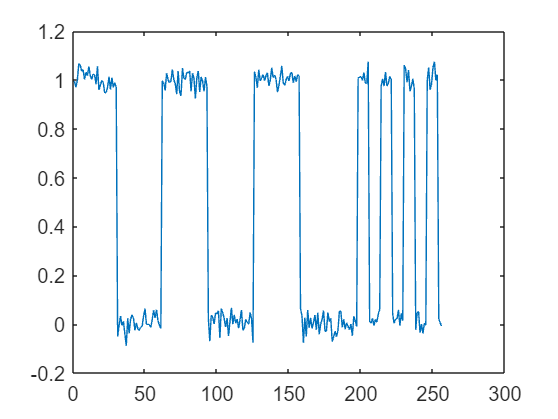

% coding params
clearvars
nchip = 4;  % number of symbols in chip

% sim params
% a 6 inch line printed at 300 dpi yields about 112 bytes per line. we
% probably need to improve on this a bit...
ndat = 128;  % number of bytes in frame
nk = 8;  % number of samples per symbol
snr = 10;
clip = randi(24);  % number of samples to clip on each end
jitter = 0.25;

xs = gentestbytes(ndat);  % pattern bytes
frm = encodeframe(xs);
sraw = simchannel(frm, nk, snr, clip, jitter);

plot(sraw(1:min(256,length(sraw))))

## precondition

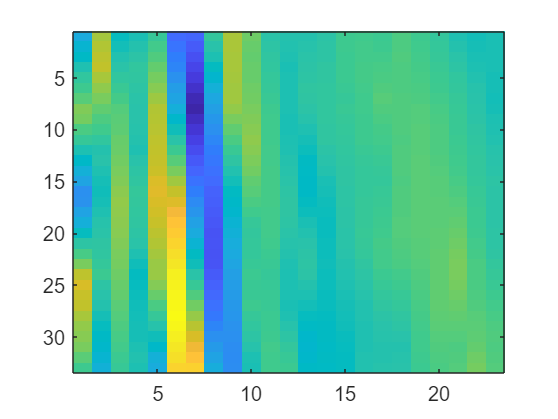

zs = [];

clips = 0:32;
scales = 2:24;
params = cell(length(clips), length(scales));
for kc = 1:length(clips)
  for ks = 1:length(scales)
    zs(kc, ks) = scorescaling(scales(ks), clips(kc), sraw); %#ok<*SAGROW>
    params{kc, ks} = [clips(kc) scales(ks)];
  end
end

imagesc(zs)


[~, kmin] = min(zs, [], 'all', 'linear');
p = params{kmin};
startk = nchip*2*3*p(2) - p(1) + 1;
s = sraw(startk:end);  % signal with fiducials removed
nsamp = p(2);  % spatial samples per symbol
s = s - mean(s);  % should eventually use a high-pass filter to remove DC term

## decode

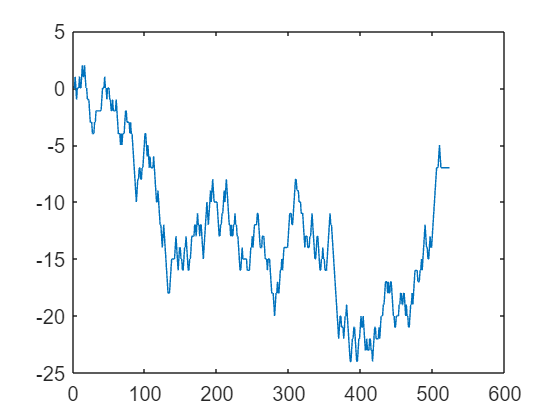

xvec0 = [-1 1 -1 1];
xvec1 = [1 -1 1 -1];
xvec2 = [-1 -1 1 1];
xvec3 = [1 1 -1 -1];
xvect1 = [1 1 1 1];
xvect2 = [-1 -1 -1 -1];

% construct decode matrix
% build filled out code matrix including onerse sample buff in
% the order: (1-left-shift; 1-no-shift; 1-right-shift; ...)
dc = [xvec0; xvec1; xvec2; xvec3];
[ncode, nchip] = size(dc);
decmat = zeros(ncode + 1, nchip*nsamp+2);
for k = 1:ncode  
  scode = zoh(dc(k,:), nsamp);
  decmat(k,:) = [scode 0 0];
  decmat(k+ncode,:) = [0 scode 0];
  decmat(k+2*ncode,:) = [0 0 scode];
end
decmat(end+1:end+2,:) = [0 zoh(xvect1, nsamp) 0; 0 zoh(xvect2, nsamp) 0];

% construct code matrix (what it all means)
% [code, sample offset]
codmat = ...
  [0 -1; 1 -1; 2 -1; 3 -1; ...
  0 0; 1 0; 2 0; 3 0; ...
  0 1; 1 1; 2 1; 3 1;
  4 0; 5 0];

% go through and pull out windows for decoding single chips. another
% approach to try is convolving each code with the entire signal, and then
% going back and figuring out each maximum likelihood detection afterwards.
% not as easy, probably, but much more computationally efficient. no
% premature optimization, though...
termsig = false;
ns = length(s);
nchipest = floor(ns/nchip/nsamp);
xchipraw = uint8(zeros(1, nchipest));  % 2-bit chip decode buffer
ks = 1;  % index into signal vector
kx = 1;  % index into decoded chip vector
stride = nchip*nsamp + 1;
shimlog = zeros(1, nchipest);
while ((ks+stride) < ns)
  schip = s(ks:(ks+stride));  % get signal with buffer
  dec = decmat*schip(:);
  [m, kmax] = max(dec);
  maxlik = codmat(kmax,:);
  xchipraw(kx) = maxlik(1);
  shim = double(maxlik(2));  % scan adjustment, should eventually use PLL
  shimlog(kx) = shim;
  ks = ks + nsamp*nchip + shim;  % advance decode window
  kx = kx + 1;
end

plot(cumsum(shimlog))

## combine chips into bytes

xchips = xchipraw(xchipraw < 4);
xdecs = uint8(zeros(1, floor(length(xchips)/nchip)));  % should check if div by nchip
for kd = 1:length(xdecs)
  kchip = nchip*(kd-1) + 1;
  xchip = xchips(kchip:(kchip+nchip-1));
  x = 2^6*xchip(1) + 2^4*xchip(2) + 2^2*xchip(3) + xchip(4);
  xdecs(kd) = x;
end

## error checking

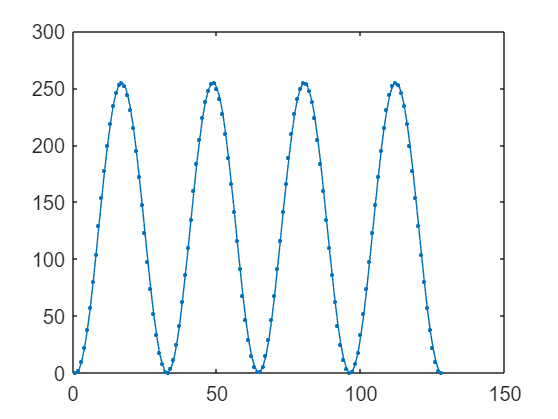

plot(xdecs, '.-')